# USV Exploration of model-based controllers and GPR ML model

## **Nonlinear && Llinear Model Predictive Controller & Full State Feeback Controller Studies **

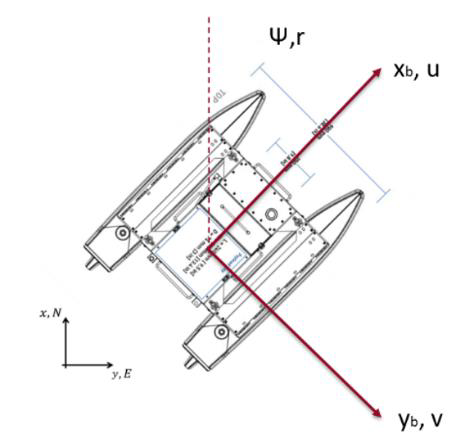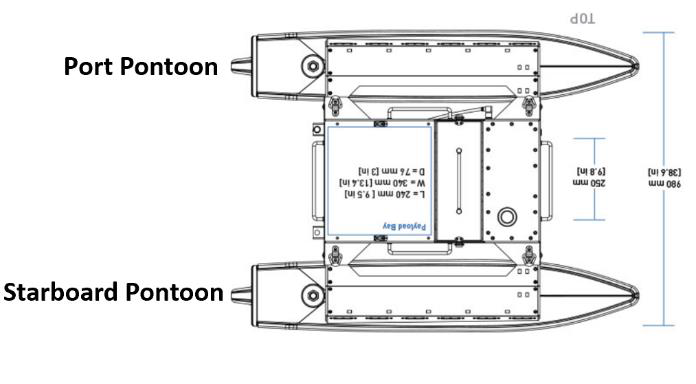

Let's recover the vehicle model of its kinematic and dynamic combination:

$q={{\left[\begin{array}{cc}
\begin{array}{ccc}
x & y & \psi 
\end{array} & \begin{array}{ccc}
u & v & r
\end{array}
\end{array}\right]}}^T$ == our USV state spaces vector


$$\dot{q} ={{\left[\begin{array}{cc}
\begin{array}{ccc}
\dot{x}  & \dot{y}  & \dot{\psi} 
\end{array} & \begin{array}{ccc}
\dot{u}  & \dot{v}  & \dot{r} 
\end{array}
\end{array}\right]}}^T$$


$\tau ={\left\lbrack \begin{array}{ccc}
\tau_x  & \tau_y  & \tau_z 
\end{array}\right\rbrack }^T$ == input USV resultant force and moment vector   


$$\dot{q} ={\left[\begin{array}{c}
\begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{\psi} 
\end{array}\\
\begin{array}{c}
\dot{u} \\
\dot{v} \\
\dot{r} 
\end{array}
\end{array}\right]}={\left[\begin{array}{cc}
0_{3\times 3}  & \begin{array}{ccc}
\cos \psi  & -\sin \psi  & 0\\
\sin \psi  & \cos \psi  & 0\\
0 & 0 & 1
\end{array}\\
0_{3\times 3}  & \begin{array}{ccc}
-\frac{X_u }{M{\left(1,1\right)}} & \frac{M{\left(2,2\right)}r}{M{\left(1,1\right)}} & 0\\
0 & -\frac{Y_v }{M{\left(2,2\right)}} & \frac{M{\left(1,1\right)}u}{M{\left(2,2\right)}}\\
\frac{M{\left(1,1\right)}-M{\left(2,2\right)}}{M{\left(3,3\right)}}v & 0 & -\frac{N_r }{M{\left(3,3\right)}}
\end{array}
\end{array}\right]}{\left[\begin{array}{c}
\begin{array}{c}
x\\
y\\
\psi 
\end{array}\\
\begin{array}{c}
u\\
v\\
r
\end{array}
\end{array}\right]}+{\left[\begin{array}{c}
0_{3\times 3} \\
\begin{array}{ccc}
\frac{1}{M{\left(1,1\right)}} & 0 & 0\\
0 & \frac{1}{M{\left(2,2\right)}} & 0\\
0 & 0 & \frac{1}{M{\left(3,3\right)}}
\end{array}
\end{array}\right]}{\left[\begin{array}{c}
\tau_x \\
\tau_y \\
\tau_z 
\end{array}\right]}$$


This section will discover linear and nonlinear MPC controller to realize trajecties tracking challenge and compare full state feedback controller to analyze their tracking performance. Our designed controllers are defined as:

- Linear MPC (Traditional Linear && Hybrid Linear) 

- Nonlinear MPC (Approximate Local Linearization technique)

- Linear full state feedback (PD + Feedback Linearization)

- Nonlinear full state feedback controller (PID + Approximate Linearization)   

### Section 1.1: Prompt physical data from Main898 to this file

m = 38; % mass of Heron M300(kg) within payload mass 
L = 1.3; % length of Heron M300(m)
W = 0.98; % width of Heron M300(m)
H = 0.32; % height of Heron M300(m)
%H_antenna = 0.74; % height within the antenna element(m)
Drought = 0.12; % Drought of Heron M300(m)
B_hull = 0.24; % beam of the individual pontoon
B = 0.74; % beam of Heron M300(m)
LCG = 0.49; % longitudinal centre of gravity wrt plane og engine

U_max = 1.7; % maximum speed of the boat(m/s)
U = 1; % normal speed of the boat(m/s)
T_port_max = 20; % maximum thruster force of the port right pontoon(N)
T_starboard_max = 20; % maximum thruster force of the starboard left pontoon(N)
Power = 70; % total drive power(W)
rho_water = 997; % water density(kg/m^3)
rho_air = 1.2754; % air density(kg/m^3)
X_u_dot = -0.05*m; % added mass coefficient in surge direction from surge acceleration(kg)
Y_v_dot = -0.5*pi*rho_water*(Drought^2)*L; % added mass coefficient in sway direction from sway acceleration(kg)
N_r_dot = -(1/24)*(0.1*m*(B^2) + rho_water*pi*(Drought^2)*(L^3));% added mass coefficient from yaw acceleration(kg*m^2)


I_z = 6.25; % estimated mass moment of inertia about z axis(kg*m^2)
M = [m-X_u_dot 0 0;0 m-Y_v_dot 0;0 0 I_z-N_r_dot]; % Mass matrix
D = [26.43 0 0;0 72.64 0;0 0 22.96]; % linear drag term


### Section 1.2: Set up simulation parameter

simutime = 63; % total time 63
t = 0.01; % time step
T = 0:t:simutime; % total time step vector__300 seconds
N = length(T);


### Section 1.3: Simulate referenced trajectory

q_d = zeros(6,N); % desired state of the USV
q_d_dot = zeros(6,N);
tao_d = zeros(3,N);
f_d = zeros(2,N);
err_FSF = zeros(6,N);


bigR = 0.8*(1/24)*(N)*0.01;
traj = input(' 1. Infinite Loop \n 2. Race Path \n ');
switch traj
    
    case 1
        for k = 2:N % small square trajectory
            if (k <= (N)/10)
                q_d(4,k-1) = 0.5;
                q_d(6,k-1) = 0;
                [q_d(1:3,k),q_d(4:6,k)]= Vehicle(q_d_dot(1:3,k-1),q_d_dot(4:6,k-1),q_d(1:3,k-1),q_d(4:6,k-1),t);
                q_d_dot(1:3,k) = [cos(q_d(3,k)) -sin(q_d(3,k)) 0;
                               sin(q_d(3,k)) cos(q_d(3,k)) 0;
                               0 0 1] * q_d(4:6,k);
            
                elseif (k > (N)/10) && (k <= 4*(N)/10)
                    q_d(4,k-1) = pi/4;
                    q_d(6,k-1) = (pi-(17*pi/360))/12;
                    [q_d(1:3,k),q_d(4:6,k)]= Vehicle(q_d_dot(1:3,k-1),q_d_dot(4:6,k-1),q_d(1:3,k-1),q_d(4:6,k-1),t);
                    q_d_dot(1:3,k) = [cos(q_d(3,k)) -sin(q_d(3,k)) 0;
                               sin(q_d(3,k)) cos(q_d(3,k)) 0;
                               0 0 1] * q_d(4:6,k);
                
                elseif (k > 4*(N)/10) && (k <= 6*(N)/10) 
                    q_d(4,k-1) = 0.5;
                    q_d(6,k-1) = 0;
                    [q_d(1:3,k),q_d(4:6,k)]= Vehicle(q_d_dot(1:3,k-1),q_d_dot(4:6,k-1),q_d(1:3,k-1),q_d(4:6,k-1),t);
                    q_d_dot(1:3,k) = [cos(q_d(3,k)) -sin(q_d(3,k)) 0;
                               sin(q_d(3,k)) cos(q_d(3,k)) 0;
                               0 0 1] * q_d(4:6,k);
                    
                elseif (k > 6*(N)/10) && (k <= 9*(N)/10) 
                    q_d(4,k-1) = pi/4;
                    q_d(6,k-1) = -(pi-(17*pi/360))/12;
                    [q_d(1:3,k),q_d(4:6,k)]= Vehicle(q_d_dot(1:3,k-1),q_d_dot(4:6,k-1),q_d(1:3,k-1),q_d(4:6,k-1),t);
                    q_d_dot(1:3,k) = [cos(q_d(3,k)) -sin(q_d(3,k)) 0;
                               sin(q_d(3,k)) cos(q_d(3,k)) 0;
                               0 0 1] * q_d(4:6,k);
                else
                    q_d(4,k-1) = 0.9;
                    q_d(6,k-1) = 0;
                    [q_d(1:3,k),q_d(4:6,k)]= Vehicle(q_d_dot(1:3,k-1),q_d_dot(4:6,k-1),q_d(1:3,k-1),q_d(4:6,k-1),t);
                    q_d_dot(1:3,k) = [cos(q_d(3,k)) -sin(q_d(3,k)) 0;
                               sin(q_d(3,k)) cos(q_d(3,k)) 0;
                               0 0 1] * q_d(4:6,k);
            end
        end


% Second design trajectory
    case 2
        for k = 2:N % small square trajectory
        
            if (k <= 2*(N)/12)
                q_d(4,k-1) = 0.8+0.0005*k*t;
                q_d(6,k-1) = 0;
                [q_d(1:3,k),q_d(4:6,k)]= Vehicle(q_d_dot(1:3,k-1),q_d_dot(4:6,k-1),q_d(1:3,k-1),q_d(4:6,k-1),t);
                q_d_dot(1:3,k) = [cos(q_d(3,k)) -sin(q_d(3,k)) 0;
                                  sin(q_d(3,k)) cos(q_d(3,k)) 0;
                                  0 0 1] * q_d(4:6,k);             
                elseif (k > 2*(N)/12) && (k <= 4*(N)/12)
                    q_d(3,k-1) = pi/2;
                    q_d(4,k-1) = 0.8;
                    q_d(6,k-1) =0;
                    [q_d(1:3,k),q_d(4:6,k)]= Vehicle(q_d_dot(1:3,k-1),q_d_dot(4:6,k-1),q_d(1:3,k-1),q_d(4:6,k-1),t);
                    q_d_dot(1:3,k) = [cos(q_d(3,k)) -sin(q_d(3,k)) 0;
                                      sin(q_d(3,k)) cos(q_d(3,k)) 0;
                                      0 0 1] * q_d(4:6,k);    
                
                elseif (k > 4*(N)/12) && (k <= 6*(N)/12)    
                    q_d(4,k-1) = 6*pi*bigR/((N)*0.01);
                    q_d(6,k-1) = -6*pi/((N)*0.01);
                    [q_d(1:3,k),q_d(4:6,k)]= Vehicle(q_d_dot(1:3,k-1),q_d_dot(4:6,k-1),q_d(1:3,k-1),q_d(4:6,k-1),t);
                    q_d_dot(1:3,k) = [cos(q_d(3,k)) -sin(q_d(3,k)) 0;
                                      sin(q_d(3,k)) cos(q_d(3,k)) 0;
                                      0 0 1] * q_d(4:6,k);  
                                  
                elseif (k > 6*(N)/12) && (k <= 8*(N)/12)  
                    q_d(4,k-1) = 1.6;
                    q_d(6,k-1) = 0;
                    [q_d(1:3,k),q_d(4:6,k)]= Vehicle(q_d_dot(1:3,k-1),q_d_dot(4:6,k-1),q_d(1:3,k-1),q_d(4:6,k-1),t);
                    q_d_dot(1:3,k) = [cos(q_d(3,k)) -sin(q_d(3,k)) 0;
                                      sin(q_d(3,k)) cos(q_d(3,k)) 0;
                                      0 0 1] * q_d(4:6,k); 
                                  
                elseif (k > 8*(N)/12) && (k <= 10*(N)/12)  
                    q_d(4,k-1) = 6*pi*bigR/((N)*0.01);
                    q_d(6,k-1) = 6*pi/((N)*0.01);
                    [q_d(1:3,k),q_d(4:6,k)]= Vehicle(q_d_dot(1:3,k-1),q_d_dot(4:6,k-1),q_d(1:3,k-1),q_d(4:6,k-1),t);
                    q_d_dot(1:3,k) = [cos(q_d(3,k)) -sin(q_d(3,k)) 0;
                                      sin(q_d(3,k)) cos(q_d(3,k)) 0;
                                      0 0 1] * q_d(4:6,k); 
                                  
                                  
                else 
                    q_d(4,k-1) = 1.6;
                    q_d(6,k-1) = 0;
                    [q_d(1:3,k),q_d(4:6,k)]= Vehicle(q_d_dot(1:3,k-1),q_d_dot(4:6,k-1),q_d(1:3,k-1),q_d(4:6,k-1),t);
                    q_d_dot(1:3,k) = [cos(q_d(3,k)) -sin(q_d(3,k)) 0;
                                      sin(q_d(3,k)) cos(q_d(3,k)) 0;
                                      0 0 1] * q_d(4:6,k);                
            end
        end
end


 Introduce desired input force by computing pseudo-inverse to this least-square problem for the feedforward PID controller design: 

for k = 1:N
    tao_d(:,k) = M * q_d_dot(4:6,k) + [0 0 -M(2,2)*q_d(5,k);0 0 M(1,1)*q_d(4,k);M(2,2)*q_d(5,k) -M(1,1)*q_d(4,k) 0]*q_d(4:6,k) + D * q_d(4:6,k); 
end

Interpolate/resize the indexing duration of the desired data to cater for the lookahead horizon points simulation for MPC.

The size of the indexing will depend on p. Sometimes, lookahead points p will not always generate the same length as the indexing legnth after interpolation. Therefore, we will adjust our p points to the length of the new index arrayAnother way of adding extra horizontal pointa is to assign the rest time p to the first p time slices of the desired state vector. It is likely that Another way will be more easier. “i_opt” may act as the number of optimization linearization per time step.

% p_horizon for 150 for NMPC, otherwize p_horizon for 100 
p_horizon = 1:100;
p = length(p_horizon);
q_d_new = zeros(6,N+p);
q_d_dot_new = zeros(6,N+p);
q_d_new(:,1:N) = q_d(:,1:N);
q_d_dot_new(:,1:N) = q_d_dot(:,1:N);
for k = 1:p
    q_d_new(4,N+k-1) = q_d(4,k);
    q_d_new(6,N+k-1) = q_d(6,k);
    [q_d_new(1:3,N+k),q_d_new(4:6,N+k)]= Vehicle(q_d_dot_new(1:3,N+k-1),q_d_dot_new(4:6,N+k-1),q_d_new(1:3,N+k-1),q_d_new(4:6,N+k-1),t);
    q_d_dot_new(1:3,N+k) = [cos(q_d_new(3,k)) -sin(q_d_new(3,k)) 0;
                      sin(q_d_new(3,k)) cos(q_d_new(3,k)) 0;
                      0 0 1] * q_d_new(4:6,k);  
end

### Section 1.5: Environmental disturbances

wind part initialization

V_w = zeros(1,N); % true wind speed
V_w_ini = 3;
V_w(1,1) = V_w_ini;
v_w = zeros(2,N); % true wind velocity vector
beta_w = zeros(1,N); % true wind angle vector
beta_w(1,1) = pi/12;
Drift_wave = zeros(3,N);
for a = 2:N
    [beta_w(1,a)] = RandomWalk(beta_w(1,a-1),0.009);
    [V_w(1,a)] = RandomWalk(V_w(1,a-1),0.009);
    [Drift_wave(:,a)] = RandomWalk(Drift_wave(:,a-1),0.0009);
end
tao_wind = zeros(3,N);

wave part initialization

Hs = [8;9.5;8.45]; % define the significant height m
omega_o = 0.8; % angular peak frequency rad/s
omega_max = 3; % angular maximum frequency rad/s
omega_range = 0.0001:t:omega_max;% define a wave sequence wrt period
lambda_wave = 0.2;

%% Generate the wave model in X, Y, and N
S1 = torset_spec(Hs(1),omega_o,omega_range);
S2 = torset_spec(Hs(2),omega_o,omega_range);
S3 = torset_spec(Hs(3),omega_o,omega_range);
%% Generate the wave model in X, Y, and N

omega = repmat(omega_range,1,floor(N/length(omega_range)));
omega = cat(2,omega,omega(1,1:N-floor(N/length(omega_range))*length(omega_range)));
PSD_wave = [S1 S2 S3]'; % Construct the wave model during omega range
PSD_wave = repmat(PSD_wave,1,floor(N/length(omega_range))); % Reconstruct the wave model to simulation time duration 
PSD_wave = cat(2,PSD_wave,PSD_wave(:,1:N-floor(N/length(omega_range))*length(omega_range)));
tao_wave = zeros(3,N);


### Section 2.1: USV States Initialization && Set-up parameters 

#### Feedback Linearization definition

A_FSF = [0 1 0 0 0 0;
        0 0 0 0 0 0;
        0 0 0 1 0 0;
        0 0 0 0 0 0;
        0 0 0 0 0 1;
        0 0 0 0 0 0];
B_FSF = [0 0 0;
        1 0 0;
        0 0 0;
        0 1 0;
        0 0 0;
        0 0 1];
%pole_FSF = [-7.7 -5.8 -4.5 -5.9 -3.6 -3]; % least error but not desirable
pole_FSF = [-1 -0.35 -1.2 -0.55 -1.3 -0.6];
K_FSF_MATRIX = place(A_FSF,B_FSF,pole_FSF);

#### PID Control

%% Control part initialization
q_PID = zeros(6,N); % x y psi u v r
tao_PID = zeros(3,N);
f_PID = zeros(2,N);
q_PID(1:3,1) = [0.5 1 pi/6]';% Set up initial conditions
q_dot_PID = zeros(6,N);
K_gain = zeros(3,9,N);
uI = zeros(3,N);
Integral_term = zeros(3,N);
%% Estimator part initialization
q_hat_PID = zeros(6,N);
aa = [0.3 -0.3 0.1 0.1 0.1 0.1]; 
q_guess = q_PID(:,1);

P_guess = diag([5 -5 1 1 1 1].^2);  % Set the initial pose covariance estimate as a diagonal matrix

q_hat_PID(:,1) = q_guess + transpose(aa); % set the initial guess for estimator

z_m = zeros(6,N);% measurement odemetry and GPS signal, as well as IMU unit
u_m = zeros(3,N); % input value with noise

R_EKF = diag([0.5 0.5 0.5 0.05 0.05 0.05].^2);% Set the true process and measurement noise covariances (output measurement noise)
Q_EKF = diag([0.1 0.1 0.1].^2); %(input processing noise)

P_hat_PID = zeros(6,6,N); % Define covariance matrix
P_hat_PID(:,:,1) = P_guess;

####  FSF (Full State Feedback Control)

q_FSF = zeros(6,N); % x y psi u v r
tao_FSF = zeros(3,N);
f_FSF = zeros(2,N);
q_FSF(1:3,1) = [0.5 1 pi/6]';% Set up initial conditions
q_dot_FSF = zeros(6,N);
a_n = zeros(3,N);
a_b = zeros(3,N);
G = zeros(6,3);
G(4,1) = 1/M(1,1);
G(5,2) = 1/M(2,2);
G(6,3) = 1/M(3,3);

%% Estimator part initialization
q_hat_FSF = zeros(6,N);
aa = [0.3 -0.3 0.1 0.1 0.1 0.1]; 
P_hat_FSF = zeros(6,6,N); % Define covariance matrix
P_hat_FSF(:,:,1) = P_guess;
q_hat_FSF(:,1) = q_guess + transpose(aa); % set the initial guess for estimator

#### Linear MPC (Model Predictive Control)

F_MPC = eye(6) + t * A_FSF;
G_MPC = t * B_FSF; 
[nr,nc] = size(G_MPC);
q_MPC = zeros(nr,N);
q_MPC(1:3,1) = [0.5 1 pi/6]';
z_MPC = zeros(nr,N);

q_dot_MPC = zeros(nr,N);
tao_MPC = zeros(nc,N);
f_MPC = zeros(2,N);
eta_MPC = zeros(nc,N);

L_MPC = zeros(nr*p,nr);
M_MPC = zeros(nr*p,nc*p);
for i =1:p
    L_MPC(nr*i-nr+1:nr*i, 1:nr) = mpower(F_MPC, i);
    for j =1:p-i+1
        M_MPC(nr*(p-i+1)-nr+1:nr*(p-i+1), nc*j-nc+1:nc*j) = mpower(F_MPC, p-i-j+1) * G_MPC;
    end
end

Q_MPC = 1 * kron(eye(p),eye(nr)); % State Cost
R_MPC = 0.36 * kron(eye(p),eye(nc)); % Input Cost 

K_MPC = (transpose(M_MPC)*Q_MPC*M_MPC + R_MPC) \ transpose(M_MPC) * Q_MPC;

Zd_MPC = zeros(nr*p,1); % For only MPC use
Zd_NMPC = zeros(nr*p,1); % For only NMPC use

%% Estimator part initialization
q_hat_MPC = zeros(6,N);
aa = [0.3 -0.3 0.1 0.1 0.1 0.1]; 
P_guess = diag([5 -5 1 1 1 1].^2);  % Set the initial pose covariance estimate as a diagonal matrix
P_hat_MPC = zeros(6,6,N); % Define covariance matrix
P_hat_MPC(:,:,1) = P_guess;
q_hat_MPC(:,1) = q_guess + transpose(aa); % set the initial guess for estimator

#### NMPC (Nonlinear)

q_NMPC = zeros(nr,N+p);
q_NMPC(1:3,1) = [0.5 1 pi/6]';
z_NMPC = zeros(nr*p,1);
q_dot_NMPC = zeros(nr,N+p);
tao_NMPC = zeros(nc,N+p);
f_NMPC = zeros(2,N);
F_NMPC = zeros(6,6,N+p);
G_NMPC = t*cat(1,zeros(3),inv(M));
Hu_NMPC = kron(eye(p),G_NMPC); % wrt to M_NMPC = zeros(nr*p,nc*p);
Hz_NMPC = zeros(nr*p+nr,nr*p); % wrt to M_NMPC = zeros(nr*p,nc*p);

M_NMPC = zeros(nr*p,nc*p); 
Q_NMPC = 2500 * kron(eye(p),eye(nr)); % 2500
L_NMPC = zeros(nr*p,nr);
R_NMPC = 0.4 * kron(eye(p),eye(nc)); % 0.5
eta_NMPC = zeros(nc,N+p);
new_eta = zeros(nc*p,1);

%% Estimator part initialization
q_hat_NMPC = zeros(6,N+p); 
P_guess = diag([5 -5 1 1 1 1].^2);  % Set the initial pose covariance estimate as a diagonal matrix
P_hat_NMPC = zeros(6,6,N); % Define covariance matrix
P_hat_NMPC(:,:,1) = P_guess;
q_hat_NMPC(:,1) = q_guess + transpose(aa); % set the initial guess for estimator
u_m_NMPC = zeros(3,N+p);

#### Hybrid Linear MPC

q_HMPC = zeros(nr,N+p);
q_dot_HMPC = zeros(nr,N+p);
q_HMPC(1:3,1) = [0.5 1 pi/6]';
z_HMPC = zeros(nr*p,N);
eta_HMPC = zeros(nc,N+p);
tao_HMPC = zeros(nc,N);
f_HMPC = zeros(2,N);
delta_z = zeros(nr,N);
eta_lookbehind = zeros(nc*p,1);

F_HMPC = eye(6) + t * A_FSF;
G_HMPC = t * B_FSF; 
Q_HMPC = 0.3 * kron(eye(p),eye(nr));% 0.3 1 //0.3
R_HMPC = 0.2 * kron(eye(p),eye(nc)); % 0.095 0.3135 for the second //0.2

for i =1:p
    L_HMPC(nr*i-nr+1:nr*i, 1:nr) = mpower(F_HMPC, i);
    for j =1:p-i+1
        M_HMPC(nr*(p-i+1)-nr+1:nr*(p-i+1), nc*j-nc+1:nc*j) = mpower(F_HMPC, p-i-j+1) * G_HMPC;
    end
end
K_HMPC = (transpose(M_HMPC)*Q_HMPC*M_HMPC + R_HMPC);

%% Estimator part initialization
q_hat_HMPC = zeros(6,N+p); 
P_guess = diag([5 -5 1 1 1 1].^2);  % Set the initial pose covariance estimate as a diagonal matrix
P_hat_HMPC = zeros(6,6,N); % Define covariance matrix
P_hat_HMPC(:,:,1) = P_guess;
q_hat_HMPC(:,1) = q_guess + transpose(aa); % set the initial guess for estimator

### Section 2.2: Simulate the closed-loop control system for each control algorithm

#### PID Control with Approximate Linearization without desired resultant force and moment inputs

Details of the PID control algorithm are explained in Main898.mlx file and click to the file if you are interested!

tic
for i = 2:N
    %% Simulate PID Controller
    [K_gain(:,:,i-1), tao_PID(:,i-1),Integral_term(:,i-1)] = FSF_PID(q_hat_PID(:,i-1), q_d(:,i), M, D, X_u_dot, Y_v_dot, tao_d(:,i), t, uI(:,i-1), i);
    tao_wave(1,i-1) = ExwaveForce(PSD_wave(1,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_PID(:,i-1),Drift_wave(1,i));
    tao_wave(2,i-1) = ExwaveForce(PSD_wave(2,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_PID(:,i-1),Drift_wave(2,i));
    tao_wave(3,i-1) = ExwaveForce(PSD_wave(3,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_PID(:,i-1),Drift_wave(3,i));
    tao_wind(:,i-1) = ExwindForce(beta_w(1,i),V_w(1,i),q_FSF(4:6,i-1),q_PID(3,i-1),rho_air,L);   
%    [tao_PID(1,i-1),tao_PID(3,i-1)] = sat(tao_PID(1,i-1),tao_PID(3,i-1));
    

    f_PID(1,i-1) = tao_PID(1,i-1)*0.5 + tao_PID(3,i-1)/B;
    f_PID(2,i-1) = tao_PID(1,i-1)*0.5 - tao_PID(3,i-1)/B;
   % tao_PID(:,i-1) = tao_PID(:,i-1) - tao_wind(:,i-1) - tao_wave(:,i-1);
    [q_dot_PID(1:3,i-1),q_dot_PID(4:6,i-1)] = HERON(X_u_dot,Y_v_dot,N_r_dot,I_z,q_PID(4:6,i-1),tao_PID(:,i-1),q_PID(1:3,i-1),t);
    [q_PID(1:3,i),q_PID(4:6,i)]= Vehicle(q_dot_PID(1:3,i-1),q_dot_PID(4:6,i-1),q_PID(1:3,i-1),q_PID(4:6,i-1), t);    
    
    %% Model propriocdeptive sensors with processing noise
    u_m(1,i-1) = tao_PID(1,i-1) + sqrt(Q_EKF(1,1))*randn(1); 
    u_m(2,i-1) = tao_PID(2,i-1) + sqrt(Q_EKF(2,2))*randn(1);
    u_m(3,i-1) = tao_PID(3,i-1) + sqrt(Q_EKF(3,3))*randn(1);
        
    %% Model GPS,COMPASS and IMU with noise    
    z_m(1,i) = q_PID(1,i) + sqrt(R_EKF(1,1))*randn(1);
    z_m(2,i) = q_PID(2,i) + sqrt(R_EKF(2,2))*randn(1);
    z_m(3,i) = q_PID(3,i) + sqrt(R_EKF(3,3))*randn(1);
    z_m(4,i) = q_PID(4,i) + sqrt(R_EKF(4,4))*randn(1);
    z_m(5,i) = q_PID(5,i) + sqrt(R_EKF(5,5))*randn(1);
    z_m(6,i) = q_PID(6,i) + sqrt(R_EKF(6,6))*randn(1);
    
    %% Simulate EKF fusion of GPS 
    [q_hat_PID(:,i),P_hat_PID(:,:,i)] = Sensor_EKF(D,M,X_u_dot,Y_v_dot,t,q_hat_PID(:,i-1),u_m(:,i-1),z_m(:,i),R_EKF,Q_EKF,P_hat_PID(:,:,i-1));
end
toc

Elapsed time is 39.336174 seconds.


#### Full State Feedback Control (PD + FBL)

Before the FSF control technique is derived, there are some extra equations used to help us to figure out the inputs and outputs of the controller and transformation of the states from controller to the USV:

Take derivatives to the vehicle kinematic equation:

$\ddot{\eta} =\dot{J\left(\eta \right)} \left\lbrack \begin{array}{c}
u\\
v\\
r
\end{array}\right\rbrack +J\left(\eta \right)\left\lbrack \begin{array}{c}
\dot{u} \\
\dot{v} \\
\dot{r} 
\end{array}\right\rbrack$    (*)

Let $z$ be the output of the controller and $\eta$ be the input of the controller


$$z=\left\lbrack \begin{array}{c}
\varepsilon_x \\
\dot{\varepsilon_x } \\
\varepsilon_y \\
\dot{\varepsilon_y } \\
\varepsilon_{\psi } \\
\dot{\varepsilon_{\psi } } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x-x_d \\
\dot{x} -\dot{x_d } \\
y-y_d \\
\dot{y} -\dot{y_d } \\
\psi -\psi_d \\
\dot{\psi} -\dot{\psi_d } 
\end{array}\right\rbrack$$



$$\dot{z} =\mathrm{Az}+B\;\eta =\left\lbrack \begin{array}{cccccc}
0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\varepsilon_x \\
\dot{\varepsilon_x } \\
\varepsilon_y \\
\dot{\varepsilon_y } \\
\varepsilon_{\psi } \\
\dot{\varepsilon_{\psi } } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
1 & 0 & 0\\
0 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\eta_1 \\
\eta_2 \\
\eta_3 
\end{array}\right\rbrack$$


Using basic feedback control law u = -Kx, we have

$\eta =\left\lbrack \begin{array}{c}
\ddot{\varepsilon_x } \\
\ddot{\varepsilon_y } \\
\ddot{\varepsilon_{\psi } } 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{cccccc}
K_x^P  & K_x^D  & 0 & 0 & 0 & 0\\
0 & 0 & K_y^P  & K_y^D  & 0 & 0\\
0 & 0 & 0 & 0 & K_{\psi }^P  & K_{\psi }^D 
\end{array}\right\rbrack z$ , where the derivative and porportional gain values are computed using left hand side poles

Since the desired accleration of the routes are assumed to be zero, let's rewrite the equation:


$$\eta =\left\lbrack \begin{array}{c}
\ddot{x} \\
\ddot{y} \\
\ddot{\psi} 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{cccccc}
K_x^P  & K_x^D  & 0 & 0 & 0 & 0\\
0 & 0 & K_y^P  & K_y^D  & 0 & 0\\
0 & 0 & 0 & 0 & K_{\psi }^P  & K_{\psi }^D 
\end{array}\right\rbrack z$$
 

Using (*) to rewrite the equation and express $\left\lbrack \begin{array}{c}
\dot{u} \\
\dot{v} \\
\dot{r} 
\end{array}\right\rbrack$with respect to $\left\lbrack \begin{array}{c}
\ddot{x} \\
\ddot{y} \\
\ddot{\psi} 
\end{array}\right\rbrack$, then take the vehicle dynamics to output ${\left[\begin{array}{c}
\tau_x \\
\tau_y \\
\tau_z 
\end{array}\right]}$as inverse dynamics

tic 
for i = 2:N
    % simulate USV
    
    [q_dot_FSF(1:3,i-1),q_dot_FSF(4:6,i-1)] = HERON(X_u_dot,Y_v_dot,N_r_dot,I_z,q_FSF(4:6,i-1),tao_FSF(:,i-1),q_FSF(1:3,i-1),t);
    [q_FSF(1:3,i),q_FSF(4:6,i)]= Vehicle(q_dot_FSF(1:3,i-1),q_dot_FSF(4:6,i-1),q_FSF(1:3,i-1),q_FSF(4:6,i-1),t);
    
    %% Model propriocdeptive sensors with processing noise
    u_m(1,i-1) = tao_FSF(1,i-1) + sqrt(Q_EKF(1,1))*randn(1); 
    u_m(2,i-1) = tao_FSF(2,i-1) + sqrt(Q_EKF(2,2))*randn(1);
    u_m(3,i-1) = tao_FSF(3,i-1) + sqrt(Q_EKF(3,3))*randn(1);
        
    %% Model GPS,COMPASS and IMU with noise    
    z_m(1,i) = q_FSF(1,i) + sqrt(R_EKF(1,1))*randn(1);
    z_m(2,i) = q_FSF(2,i) + sqrt(R_EKF(2,2))*randn(1);
    z_m(3,i) = q_FSF(3,i) + sqrt(R_EKF(3,3))*randn(1);
    z_m(4,i) = q_FSF(4,i) + sqrt(R_EKF(4,4))*randn(1);
    z_m(5,i) = q_FSF(5,i) + sqrt(R_EKF(5,5))*randn(1);
    z_m(6,i) = q_FSF(6,i) + sqrt(R_EKF(6,6))*randn(1);
    
    %% Simulate EKF fusion of GPS 
    [q_hat_FSF(:,i),P_hat_FSF(:,:,i)] = Sensor_EKF(D,M,X_u_dot,Y_v_dot,t,q_hat_FSF(:,i-1),u_m(:,i-1),z_m(:,i),R_EKF,Q_EKF,P_hat_FSF(:,:,i-1));
    
    % Simulate disturbances
    % define g_0
    
    g_0(1,4) = cos(q_hat_FSF(3,i)); 
    g_0(1,5) = -sin(q_hat_FSF(3,i)); 
    g_0(2,4) = sin(q_hat_FSF(3,i)); 
    g_0(2,5) = cos(q_hat_FSF(3,i)); 
    g_0(3,6) = 1;
    g_0(4,4) = -D(1,1)/M(1,1);
    g_0(4,5) = M(2,2)*q_hat_FSF(6,i)/M(1,1);
    g_0(5,5) = -D(2,2)/M(2,2);
    g_0(5,6) = M(1,1) * q_hat_FSF(4,i)/M(2,2);
    g_0(6,4) = (M(1,1)-M(2,2)) * q_hat_FSF(5,i) / M(3,3);
    g_0(6,6) = -D(3,3) / M(3,3);
    
    % I/O linearization PD Control
    
    err_FSF(1,i) = q_hat_FSF(1,i-1) - q_d(1,i);
    err_FSF(2,i) = q_dot_FSF(1,i-1) - q_d_dot(1,i);
    err_FSF(3,i) = q_hat_FSF(2,i-1) - q_d(2,i);
    err_FSF(4,i) = q_dot_FSF(2,i-1) - q_d_dot(2,i);
    err_FSF(5,i) = q_hat_FSF(3,i-1) - q_d(3,i);
    err_FSF(6,i) = q_dot_FSF(3,i-1) - q_d_dot(3,i);
    Coriolis_FSF = [0 0 -M(2,2)*q_hat_FSF(5,i);
                0 0 M(1,1)*q_hat_FSF(4,i);
                M(2,2)*q_hat_FSF(5,i) -M(1,1)*q_hat_FSF(4,i) 0];
    a_n(:,i) = -K_FSF_MATRIX * err_FSF(:,i);
    J_dot = [-q_hat_FSF(6,i)*sin(q_hat_FSF(3,i)) -q_hat_FSF(6,i)*cos(q_hat_FSF(3,i)) 0;
             q_hat_FSF(6,i)*cos(q_hat_FSF(3,i)) -q_hat_FSF(6,i)*sin(q_hat_FSF(3,i)) 0;
             0 0 0];
    a_b(:,i) = g_0(1:3,4:6) \ (a_n(:,i) - J_dot * q_hat_FSF(4:6,i));
    tao_FSF(:,i) = M * a_b(:,i) + Coriolis_FSF * q_hat_FSF(4:6,i) + D * q_hat_FSF(4:6,i);
    f_FSF(1,i) = tao_FSF(1,i)*0.5 + tao_FSF(3,i)/B;
    f_FSF(2,i) = tao_FSF(1,i)*0.5 - tao_FSF(3,i)/B;
    
    % Simulate external disturbance that exerts to the body
    tao_wave(1,i) = ExwaveForce(PSD_wave(1,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_FSF(:,i),Drift_wave(1,i));
    tao_wave(2,i) = ExwaveForce(PSD_wave(2,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_FSF(:,i),Drift_wave(2,i));
    tao_wave(3,i) = ExwaveForce(PSD_wave(3,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_FSF(:,i),Drift_wave(3,i));
    tao_wind(:,i) = ExwindForce(beta_w(1,i),V_w(1,i),q_FSF(4:6,i),q_FSF(3,i),rho_air,L);
    %tao_FSF(:,i) = tao_FSF(:,i) - tao_wind(:,i) - tao_wave(:,i);

    
end

toc

Elapsed time is 0.838833 seconds.


#### Linear MPC Design + FBL

MPC is a methdology attrempts to optimize the system behaviour over same prediction horizon $p\in \Re$as a discrete number of time steps in the future from the current state *k*. 

Suppose that *p is an array *$\left\lbrack \begin{array}{cccc}
1 & 2 & \cdots  & p
\end{array}\right\rbrack$ and define a cost function$J\left(\vec{\eta} \right)={\left(\vec{z_d } -\vec{z} \right)}^T Q\left(\vec{z_d } -\vec{z} \right)+{\vec{\eta} }^T R\vec{\eta}$, where      $\;\;\;\vec{\eta} =\left\lbrack \begin{array}{ccccc}
{\ddot{x} }^{k+1}  & {\ddot{x} }^{k+2}  & {\ddot{x} }^{k+3}  & \cdots  & {\ddot{x} }^{k+p} \\
{\ddot{y} }^{k+1}  & {\ddot{y} }^{k+2}  & {\ddot{y} }^{k+3}  & \cdots  & {\ddot{y} }^{k+p} \\
{\ddot{\psi} }^{k+1}  & {\ddot{\psi} }^{k+2}  & {\ddot{\psi} }^{k+3}  & \cdots  & {\ddot{\psi} }^{k+p} 
\end{array}\right\rbrack$: future input forces and moment vector

  $\vec{z} =\left\lbrack \begin{array}{ccccc}
x^{k+1}  & x^{k+2}  & x^{k+3}  & \cdots  & x^{k+p} \\
{\dot{x} }^{k+1}  & {\dot{x} }^{k+2}  & {\dot{x} }^{k+3}  & \cdots  & {\dot{x} }^{k+p} \\
y^{k+1}  & y^{k+2}  & y^{k+3}  & \cdots  & y^{k+p} \\
{\dot{y} }^{k+1}  & {\dot{y} }^{k+2}  & {\dot{y} }^{k+3}  & \cdots  & {\dot{x} }^{k+p} \\
\psi^{k+1}  & \psi^{k+2}  & \psi^{k+3}  & \cdots  & \psi^{k+p} \\
{\dot{\psi} }^{k+1}  & {\dot{\psi} }^{k+2}  & {\dot{\psi} }^{k+3}  & \cdots  & {\dot{\psi} }^{k+p} 
\end{array}\right\rbrack$: prediction outputs

  $\vec{z_d } =\left\lbrack \begin{array}{ccccc}
x_d^{k+1}  & x_d^{k+2}  & x_d^{k+3}  & \cdots  & x_d^{k+p} \\
{\dot{x} }_d^{k+1}  & {\dot{x} }_d^{k+2}  & {\dot{x} }_d^{k+3}  & \cdots  & {\dot{x} }_d^{k+p} \\
y_d^{k+1}  & y_d^{k+2}  & y_d^{k+3}  & \cdots  & y_d^{k+p} \\
{\dot{y} }_d^{k+1}  & {\dot{y} }_d^{k+2}  & {\dot{y} }_d^{k+3}  & \cdots  & {\dot{y} }_d^{k+p} \\
\psi_d^{k+1}  & \psi_d^{k+2}  & \psi_d^{k+3}  & \cdots  & \psi_d^{k+p} \\
{\dot{\psi} }_d^{k+1}  & {\dot{\psi} }_d^{k+2}  & {\dot{\psi} }_d^{k+3}  & \cdots  & {\dot{\psi} }_d^{k+3} 
\end{array}\right\rbrack$: desired outputs

Use lookhead (prediction horizon timesteps) $p\in Z_+$ and compute the MPC-based controller design matrixces  $M\in \Re^{\textrm{np}\times \textrm{np}}$ and $L\in \Re^{\textrm{np}\times n}$, and positive weighting state cost and input cost matrices that are tunable to change path following behaviours $Q\in \Re^{\textrm{np}\times \textrm{np}}$ and $R\in \Re^{\textrm{mp}\times \textrm{mp}}$ such that


$$L={\left\lbrack \begin{array}{ccccc}
F & F^2  & F^3  & \cdots  & F^p 
\end{array}\right\rbrack }^T$$



$$M=\left\lbrack \begin{array}{ccccc}
G & 0 & 0 & \cdots  & 0\\
\textrm{FG} & G & 0 & \cdots  & 0\\
{\mathrm{F}}^2 G & \textrm{FG} & G & \cdots  & 0\\
\vdots  & \vdots  & \vdots  & \vdots  & \vdots \\
F^{p-1} G & F^{p-2} G & F^{p-3} G & \cdots  & G
\end{array}\right\rbrack$$


$\vec{z} =Lz_k +M\vec{\eta}$, where $L=I_6 +\Delta t*A$ and $G=\Delta t*B$

Afterwards, we rewrite our equation as 


$$J\left(\vec{\eta} \right)={\left(\vec{z_d } -Lz_k -M\vec{\eta} \right)}^T Q\left(\vec{z_d } -Lz_k -M\vec{\eta} \right)+{\vec{\eta} }^T R\vec{\eta}$$


Optimize $\eta$ by taking partial derivatives $\frac{\partial }{\partial \vec{\eta} }J\left(\vec{\eta} \right)=0$ and rearange the equation to express $\vec{\eta}$ as:


$$\vec{\eta} ={\left(M^T \textrm{QM}+R\right)}^{-1} M^T Q\left(\vec{z_d } -Lz_k \right)$$


Take the first three values as optimized inputs $\eta_k$ in $\vec{\eta}$at time *k and use the FBL technique to change to *$\tau_k$ 

tic
for i = 2:N
    [q_dot_MPC(1:3,i-1),q_dot_MPC(4:6,i-1)] = HERON(X_u_dot,Y_v_dot,N_r_dot,I_z,q_MPC(4:6,i-1),tao_MPC(:,i-1),q_MPC(1:3,i-1),t);
    [q_MPC(1:3,i),q_MPC(4:6,i)]= Vehicle(q_dot_MPC(1:3,i-1),q_dot_MPC(4:6,i-1),q_MPC(1:3,i-1),q_MPC(4:6,i-1),t);
    
    %% Model propriocdeptive sensors with processing noise
    u_m(1,i-1) = tao_MPC(1,i-1) + sqrt(Q_EKF(1,1))*randn(1); 
    u_m(2,i-1) = tao_MPC(2,i-1) + sqrt(Q_EKF(2,2))*randn(1);
    u_m(3,i-1) = tao_MPC(3,i-1) + sqrt(Q_EKF(3,3))*randn(1);
        
    %% Model GPS,COMPASS and IMU with noise    
    z_m(1,i) = q_MPC(1,i) + sqrt(R_EKF(1,1))*randn(1);
    z_m(2,i) = q_MPC(2,i) + sqrt(R_EKF(2,2))*randn(1);
    z_m(3,i) = q_MPC(3,i) + sqrt(R_EKF(3,3))*randn(1);
    z_m(4,i) = q_MPC(4,i) + sqrt(R_EKF(4,4))*randn(1);
    z_m(5,i) = q_MPC(5,i) + sqrt(R_EKF(5,5))*randn(1);
    z_m(6,i) = q_MPC(6,i) + sqrt(R_EKF(6,6))*randn(1);
    
    %% Simulate EKF fusion of GPS 
    [q_hat_MPC(:,i),P_hat_MPC(:,:,i)] = Sensor_EKF(D,M,X_u_dot,Y_v_dot,t,q_hat_MPC(:,i-1),u_m(:,i-1),z_m(:,i),R_EKF,Q_EKF,P_hat_MPC(:,:,i-1));
    
    z_MPC(1,i-1) = q_hat_MPC(1,i-1);
    z_MPC(2,i-1) = q_dot_MPC(1,i-1);
    z_MPC(3,i-1) = q_hat_MPC(2,i-1);
    z_MPC(4,i-1) = q_dot_MPC(2,i-1);
    z_MPC(5,i-1) = q_hat_MPC(3,i-1);
    z_MPC(6,i-1) = q_dot_MPC(3,i-1);
    for j = 1:p
        Zd_MPC(nr*j-nr+1,1) = q_d_new(1,i+j-1);
        Zd_MPC(nr*j-nr+2,1) = q_d_dot_new(1,i+j-1);
        Zd_MPC(nr*j-nr+3,1) = q_d_new(2,i+j-1);
        Zd_MPC(nr*j-nr+4,1) = q_d_dot_new(2,i+j-1);
        Zd_MPC(nr*j-nr+5,1) = q_d_new(3,i+j-1);
        Zd_MPC(nr*j-nr+6,1) = q_d_dot_new(3,i+j-1);
    end
    eta = -K_MPC * (L_MPC*z_MPC(:,i-1) -Zd_MPC);
    eta_MPC(:,i) = eta(1:3);
    g_0(1,4) = cos(q_MPC(3,i)); 
    g_0(1,5) = -sin(q_MPC(3,i)); 
    g_0(2,4) = sin(q_MPC(3,i)); 
    g_0(2,5) = cos(q_MPC(3,i)); 
    g_0(3,6) = 1;
    g_0(4,4) = -D(1,1)/M(1,1);
    g_0(4,5) = M(2,2)*q_MPC(6,i)/M(1,1);
    g_0(5,5) = -D(2,2)/M(2,2);
    g_0(5,6) = M(1,1) * q_MPC(4,i)/M(2,2);
    g_0(6,4) = (M(1,1)-M(2,2)) * q_MPC(5,i) / M(3,3);
    g_0(6,6) = -D(3,3) / M(3,3);
    Coriolis_MPC = [0 0 -M(2,2)*q_MPC(5,i);
                0 0 M(1,1)*q_MPC(4,i);
                M(2,2)*q_MPC(5,i) -M(1,1)*q_MPC(4,i) 0];
    J_dot = [-q_MPC(6,i)*sin(q_MPC(3,i)) -q_MPC(6,i)*cos(q_MPC(3,i)) 0;
             q_MPC(6,i)*cos(q_MPC(3,i)) -q_MPC(6,i)*sin(q_MPC(3,i)) 0;
             0 0 0];
    eta_MPC_b = g_0(1:3,4:6) \ (eta_MPC(:,i) - J_dot * q_MPC(4:6,i));
    tao_MPC(:,i) = M * eta_MPC_b + Coriolis_MPC * q_hat_MPC(4:6,i) + D * q_MPC(4:6,i);    
%    [tao_MPC(1,i),tao_MPC(3,i)] = sat(tao_MPC(1,i),tao_MPC(3,i));
    f_MPC(1,i) = tao_MPC(1,i)*0.5 + tao_MPC(3,i)/B;
    f_MPC(2,i) = tao_MPC(1,i)*0.5 - tao_MPC(3,i)/B;
    
    % Simulate disturbance
    tao_wave(1,i) = ExwaveForce(PSD_wave(1,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_FSF(:,i),Drift_wave(1,i));
    tao_wave(2,i) = ExwaveForce(PSD_wave(2,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_FSF(:,i),Drift_wave(2,i));
    tao_wave(3,i) = ExwaveForce(PSD_wave(3,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_FSF(:,i),Drift_wave(3,i));
    tao_wind(:,i) = ExwindForce(beta_w(1,i),V_w(1,i),q_FSF(4:6,i),q_FSF(3,i),rho_air,L);
    %tao_MPC(:,i) = tao_MPC(:,i) - tao_wind(:,i) - tao_wave(:,i);
end
toc

Elapsed time is 7.161826 seconds.


#### Nonlinear MPC

Based on* p array *$\left\lbrack \begin{array}{cccc}
1 & 2 & \cdots  & p
\end{array}\right\rbrack$ and a cost function$J\left(\vec{u} \right)={\left(\vec{z_d } -\vec{z} \right)}^T Q\left(\vec{z_d } -\vec{z} \right)+{\vec{u} }^T R\vec{u}$

Redefine the the state vector$\vec{z}$as$\vec{\mathit{\mathbf{z}}} \equiv \vec{\mathit{\mathbf{q}}}$and input vector $\vec{u}$as$\vec{\mathit{\mathbf{u}}} \equiv \vec{\tau}$for NMPC

Suppose $\vec{\mathit{\mathbf{z}}} =\bar{z} +\tilde{z}$ and $\vec{u} =\bar{u} +\tilde{u}$

Based on the state space equation, we could write out$\vec{\mathit{\mathbf{z}}}$at time step *k+1* as ${\vec{\mathit{\mathbf{z}}} }_{k+1+p} =f\left({\vec{z} }_{k+p} \;,{\vec{u} }_{k+p} \right)$, where $\bar{z} ={\vec{z} }_{k+p}$ and $\bar{u} ={\vec{u} }_{k+p}$  

To use the local-linearization technique:

$f\left(x,u\right)=f\left(x_0 ,u_0 \right)+\frac{\partial }{\partial x\left|x=x_0 ,u=u_0 \right.}f\left(x,u\right)\left(x-x_0 \right)+\frac{\partial }{\partial u\left|x=x_0 ,u=u_0 \right.}f\left(x,u\right)\left(u-u_0 \right)=H_z \left(x-x_0 \right)+H_u \left(u-u_0 \right)$  to express $\tilde{z}$ at time step k as:


$${\tilde{z} }_{k+1+p} =H_z {\tilde{z} }_{k+p} +H_u {\tilde{u} }_{k+p}$$


Since current state $z_k$ is measured, then ${\tilde{z} }_{k+1+p} =H^* {\tilde{u} }_{k+p} ={\left(I-H_z \right)}^{-1} H_u {\tilde{u} }_{k+p}$

$H_z =\left\lbrack \begin{array}{cc}
0 & 0\\
\textrm{diag}\left(H_{z,k+1} ,H_{z,k+2} ,\ldotp \ldotp \ldotp H_{z,k+p} \right) & 0
\end{array}\right\rbrack$&& $H_u =\textrm{diag}\left(H_{u,k} ,H_{u,k+2} ,\ldotp \ldotp \ldotp H_{u,k+p} \right)$

Rewrite the cost function as:


$$J\left({\tilde{u} }_{k+p} \right)={\left(z_{d,k+1+p} -z_{k+p} -H^* {\tilde{u} }_{k+p} \right)}^T Q\left(z_{d,k+1+p} -z_{k+p} -H^* {\tilde{u} }_{k+p} \right)+{\left(u_{k+p} +{\tilde{u} }_{k+p} \right)}^T R\left(u_{k+p} +{\tilde{u} }_{k+p} \right)$$


Optimize ${\tilde{u} }_{k+p}$ by taking partial derivatives $\frac{\partial }{\partial {\tilde{u} }_{k+p} }J\left({\tilde{u} }_{k+p} \right)=0$ and rearange the equation to express ${\tilde{u} }_{k+p}$ as:


$${\tilde{u} }_{k+p} ={\left({H^* }^T QH^* +R\right)}^{-1} {H^* }^T Q\left\lbrack \left(z_{d,k+1+p} -z_{k+p} \right)-Ru_{k+p} \right\rbrack$$


$u_{k+1+p}$=${\bar{u} }_{k+p}$+${\tilde{u} }_{k+p}$

Take the first three values as optimized inputs $u_k$ in $u_{k+1+p}$ at time *k*

tic
for i = 2:N
    [q_dot_NMPC(1:3,i-1),q_dot_NMPC(4:6,i-1)] = HERON(X_u_dot,Y_v_dot,N_r_dot,I_z,q_NMPC(4:6,i-1),tao_NMPC(:,i-1),q_NMPC(1:3,i-1),t);
    [q_NMPC(1:3,i),q_NMPC(4:6,i)]= Vehicle(q_dot_NMPC(1:3,i-1),q_dot_NMPC(4:6,i-1),q_NMPC(1:3,i-1),q_NMPC(4:6,i-1),t); 
     
    %% Model propriocdeptive sensors with processing noise
    u_m_NMPC(1,i-1) = tao_NMPC(1,i-1) + sqrt(Q_EKF(1,1))*randn(1); 
    u_m_NMPC(2,i-1) = tao_NMPC(2,i-1) + sqrt(Q_EKF(2,2))*randn(1);
    u_m_NMPC(3,i-1) = tao_NMPC(3,i-1) + sqrt(Q_EKF(3,3))*randn(1);
        
    %% Model GPS,COMPASS and IMU with noise    
    z_m(1,i) = q_NMPC(1,i) + sqrt(R_EKF(1,1))*randn(1);
    z_m(2,i) = q_NMPC(2,i) + sqrt(R_EKF(2,2))*randn(1);
    z_m(3,i) = q_NMPC(3,i) + sqrt(R_EKF(3,3))*randn(1);
    z_m(4,i) = q_NMPC(4,i) + sqrt(R_EKF(4,4))*randn(1);
    z_m(5,i) = q_NMPC(5,i) + sqrt(R_EKF(5,5))*randn(1);
    z_m(6,i) = q_NMPC(6,i) + sqrt(R_EKF(6,6))*randn(1);
    
    %% Simulate EKF fusion of GPS 
    [q_hat_NMPC(:,i),P_hat_NMPC(:,:,i)] = Sensor_EKF(D,M,X_u_dot,Y_v_dot,t,q_hat_NMPC(:,i-1),u_m_NMPC(:,i-1),z_m(:,i),R_EKF,Q_EKF,P_hat_NMPC(:,:,i-1));
    % Update L and M
     for j =1:p 
             [q_dot_NMPC(1:3,i-1+j),q_dot_NMPC(4:6,i-1+j)] = HERON(X_u_dot,Y_v_dot,N_r_dot,I_z,q_hat_NMPC(4:6,i-1+j),u_m_NMPC(:,i-1+j),q_hat_NMPC(1:3,i-1+j),t);
             [q_hat_NMPC(1:3,i+j),q_hat_NMPC(4:6,i+j)]= Vehicle(q_dot_NMPC(1:3,i-1+j),q_dot_NMPC(4:6,i-1+j),q_hat_NMPC(1:3,i-1+j),q_hat_NMPC(4:6,i-1+j),t);
             
             F_NMPC(:,:,i-1+j) = [1 0 -t*(q_hat_NMPC(4,i-1+j)*sin(q_hat_NMPC(3,i-1+j))+q_hat_NMPC(5,i-1+j)*cos(q_hat_NMPC(3,i-1+j))) t*cos(q_hat_NMPC(3,i-1+j)) -t*sin(q_hat_NMPC(3,i-1+j)) 0;...
             0 1 t*(q_hat_NMPC(4,i-1+j)*cos(q_hat_NMPC(3,i-1+j))-q_hat_NMPC(5,i-1+j)*sin(q_hat_NMPC(3,i-1+j))) t*sin(q_hat_NMPC(3,i-1+j)) t*cos(q_hat_NMPC(3,i-1+j)) 0;...
             0 0 1 0 0 t;...
             0 0 0 1-D(1,1)*(t/M(1,1)) M(2,2)*t*q_hat_NMPC(6,i-1+j)/M(1,1) M(2,2)*t*q_hat_NMPC(5,i-1+j)/M(1,1);...
             0 0 0 -M(1,1)*q_hat_NMPC(6,i-1+j)*(t/M(2,2)) 1-D(2,2)*(t/M(2,2)) -M(1,1)*t*q_hat_NMPC(4,i-1+j)/M(2,2);...
             0 0 0 -t*(X_u_dot-Y_v_dot)*q_hat_NMPC(5,i-1+j)/M(3,3) -t*(X_u_dot-Y_v_dot)*q_hat_NMPC(4,i-1+j)/M(3,3) 1-D(3,3)*(t/M(3,3))];  
             Hz_NMPC(nr*(j+1)-5:nr*(j+1),nr*j-5:nr*j) = F_NMPC(:,:,i-1+j);
             Zd_NMPC(nr*j-nr+1:nr*j,1) = q_d_new(:,i+j);
             z_NMPC(nr*j-nr+1:nr*j,1) = q_hat_NMPC(:,i-1+j);
             tao_lookahead(nc*j-nc+1:nc*j,1) = tao_NMPC(:,i-1+j);
      end
    % Update M matrix
    M_NMPC = (eye(length(Hz_NMPC(1:nr*p,1:nr*p)))-Hz_NMPC(1:nr*p,1:nr*p)) \ Hu_NMPC; % We call it H*
    
    % Update Nonlinear gain
    K_NMPC = transpose(M_NMPC)*Q_NMPC*M_NMPC + R_NMPC;
    tao_delta = K_NMPC \ (transpose(M_NMPC)*Q_NMPC*(Zd_NMPC - z_NMPC) - R_NMPC*tao_lookahead);
    new_eta = tao_lookahead + tao_delta;
    tao_NMPC(:,i) =  new_eta(1:3);
    %[tao_NMPC(1,i),tao_NMPC(3,i)] = sat(tao_NMPC(1,i),tao_NMPC(3,i));
    f_NMPC(1,i) = tao_NMPC(1,i)*0.5 + tao_NMPC(3,i)/B;
    f_NMPC(2,i) = tao_NMPC(1,i)*0.5 - tao_NMPC(3,i)/B;
    
    % Simulate disturbance
    tao_wave(1,i) = ExwaveForce(PSD_wave(1,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_FSF(:,i),Drift_wave(1,i));
    tao_wave(2,i) = ExwaveForce(PSD_wave(2,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_FSF(:,i),Drift_wave(2,i));
    tao_wave(3,i) = ExwaveForce(PSD_wave(3,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_FSF(:,i),Drift_wave(3,i));
    tao_wind(:,i) = ExwindForce(beta_w(1,i),V_w(1,i),q_FSF(4:6,i),q_FSF(3,i),rho_air,L);   
    %tao_NMPC(:,i) = tao_NMPC(:,i) - tao_wind(:,i) - tao_wave(:,i);
end
toc

Elapsed time is 176.156839 seconds.


#### Linear Hybrid MPC

Everything is pretty similar to the traditonal one and combined with some ideas from NMPC, but the only thing modifying here is


$$\vec{z} \equiv \vec{z} -\vec{z_d }$$



$${\Delta z}_{k+1+p} =L{\Delta z}_k +M{\Delta \eta }_{k+p}$$


Redefine the cost fuction $J\left({\Delta u}_{k+p} \right)={\left({\Delta z}_{k+1+p} +z_{k+p} \right)}^T Q\left({\Delta z}_{k+1+p} +z_{k+p} \right)+{\left({\Delta \eta }_{k+1+p} +\eta_{k+p} \right)}^T R\left({\Delta \eta }_{k+1+p} +\eta_{k+p} \right)$


$${\Delta \eta }_{k+1+p} ={-\left(M^T QM+R\right)}^{-1} M^T Q\left\lbrack \left(z_{k+p} -L\Delta z_k \right)+R\eta_{k+p} \right\rbrack$$


$\eta_{k+1+p}$=$\eta_{k+p}$+${\Delta \eta }_{k+1+p}$

tic
for i = 2:N  
    [q_dot_HMPC(1:3,i-1),q_dot_HMPC(4:6,i-1)] = HERON(X_u_dot,Y_v_dot,N_r_dot,I_z,q_HMPC(4:6,i-1),tao_HMPC(:,i-1),q_HMPC(1:3,i-1),t);
    [q_HMPC(1:3,i),q_HMPC(4:6,i)]= Vehicle(q_dot_HMPC(1:3,i-1),q_dot_HMPC(4:6,i-1),q_HMPC(1:3,i-1),q_HMPC(4:6,i-1),t); 
     
     %% Model propriocdeptive sensors with processing noise
    u_m(1,i-1) = tao_HMPC(1,i-1) + sqrt(Q_EKF(1,1))*randn(1); 
    u_m(2,i-1) = tao_HMPC(2,i-1) + sqrt(Q_EKF(2,2))*randn(1);
    u_m(3,i-1) = tao_HMPC(3,i-1) + sqrt(Q_EKF(3,3))*randn(1);
        
    %% Model GPS,COMPASS and IMU with noise    
    z_m(1,i) = q_HMPC(1,i) + sqrt(R_EKF(1,1))*randn(1);
    z_m(2,i) = q_HMPC(2,i) + sqrt(R_EKF(2,2))*randn(1);
    z_m(3,i) = q_HMPC(3,i) + sqrt(R_EKF(3,3))*randn(1);
    z_m(4,i) = q_HMPC(4,i) + sqrt(R_EKF(4,4))*randn(1);
    z_m(5,i) = q_HMPC(5,i) + sqrt(R_EKF(5,5))*randn(1);
    z_m(6,i) = q_HMPC(6,i) + sqrt(R_EKF(6,6))*randn(1);
    
    %% Simulate EKF fusion of GPS 
    [q_hat_HMPC(:,i),P_hat_HMPC(:,:,i)] = Sensor_EKF(D,M,X_u_dot,Y_v_dot,t,q_hat_HMPC(:,i-1),u_m(:,i-1),z_m(:,i),R_EKF,Q_EKF,P_hat_HMPC(:,:,i-1));
    
    for j = 1:p
            g_0(1,4) = cos(q_hat_HMPC(3,i-1+j)); 
            g_0(1,5) = -sin(q_hat_HMPC(3,i-1+j)); 
            g_0(2,4) = sin(q_hat_HMPC(3,i-1+j)); 
            g_0(2,5) = cos(q_hat_HMPC(3,i-1+j)); 
            g_0(3,6) = 1;
            g_0(4,4) = -D(1,1)/M(1,1);
            g_0(4,5) = M(2,2)*q_hat_HMPC(6,i-1+j)/M(1,1);
            g_0(5,5) = -D(2,2)/M(2,2);
            g_0(5,6) = M(1,1) * q_hat_HMPC(4,i-1+j)/M(2,2);
            g_0(6,4) = (M(1,1)-M(2,2)) * q_hat_HMPC(5,i-1+j) / M(3,3);
            g_0(6,6) = -D(3,3) / M(3,3);
            Coriolis_HMPC = [0 0 -M(2,2)*q_hat_HMPC(5,i-1+j);
                        0 0 M(1,1)*q_hat_HMPC(4,i-1+j);
                        M(2,2)*q_hat_HMPC(5,i-1+j) -M(1,1)*q_hat_HMPC(4,i-1+j) 0];
            J_dot = [-q_hat_HMPC(6,i-1+j)*sin(q_hat_HMPC(3,i-1+j)) -q_hat_HMPC(6,i-1+j)*cos(q_hat_HMPC(3,i-1+j)) 0;
                    q_hat_HMPC(6,i-1+j)*cos(q_hat_HMPC(3,i-1+j)) -q_hat_HMPC(6,i-1+j)*sin(q_hat_HMPC(3,i-1+j)) 0;
                    0 0 0];           
            tao_head = M*(g_0(1:3,4:6)^(-1))*(eta_HMPC(:,i-1+j) - J_dot * q_hat_HMPC(4:6,i-1+j)) + Coriolis_HMPC * q_hat_HMPC(4:6,i-1+j) + D * q_hat_HMPC(4:6,i-1+j);               
            
            [q_dot_HMPC(1:3,i-1+j),q_dot_HMPC(4:6,i-1+j)] = HERON(X_u_dot,Y_v_dot,N_r_dot,I_z,q_hat_HMPC(4:6,i-1+j),tao_head,q_hat_HMPC(1:3,i-1+j),t);
            [q_hat_HMPC(1:3,i+j),q_hat_HMPC(4:6,i+j)]= Vehicle(q_dot_HMPC(1:3,i-1+j),q_dot_HMPC(4:6,i-1+j),q_hat_HMPC(1:3,i-1+j),q_hat_HMPC(4:6,i-1+j),t); 
            eta_lookbehind(nc*j-nc+1:nc*j,1) = eta_HMPC(:,i-1+j);            
            z_HMPC(nr*j-nr+1,i) = q_hat_HMPC(1,i+j) - q_d_new(1,i+j);
            z_HMPC(nr*j-nr+2,i) = q_dot_HMPC(1,i+j) - q_d_dot_new(1,i+j);
            z_HMPC(nr*j-nr+3,i) = q_hat_HMPC(2,i+j) - q_d_new(2,i+j);
            z_HMPC(nr*j-nr+4,i) = q_dot_HMPC(2,i+j) - q_d_dot_new(2,i+j);
            z_HMPC(nr*j-nr+5,i) = q_hat_HMPC(3,i+j) - q_d_new(3,i+j);
            z_HMPC(nr*j-nr+6,i) = q_dot_HMPC(3,i+j) - q_d_dot_new(3,i+j);  
    end
    delta_z(:,i) = z_HMPC(1:6,i) - z_HMPC(1:6,i-1);
    new_eta = -K_HMPC \ (transpose(M_HMPC)*Q_HMPC*((z_HMPC(:,i) + L_HMPC * delta_z(:,i))) + R_HMPC * eta_lookbehind); % delta eta
    eta = new_eta + eta_lookbehind;
    eta_HMPC(:,i) = eta(1:3);
    g_0(1,4) = cos(q_HMPC(3,i)); 
    g_0(1,5) = -sin(q_HMPC(3,i)); 
    g_0(2,4) = sin(q_HMPC(3,i)); 
    g_0(2,5) = cos(q_HMPC(3,i)); 
    g_0(3,6) = 1;
    g_0(4,4) = -D(1,1)/M(1,1);
    g_0(4,5) = M(2,2)*q_HMPC(6,i)/M(1,1);
    g_0(5,5) = -D(2,2)/M(2,2);
    g_0(5,6) = M(1,1) * q_HMPC(4,i)/M(2,2);
    g_0(6,4) = (M(1,1)-M(2,2)) * q_HMPC(5,i) / M(3,3);
    g_0(6,6) = -D(3,3) / M(3,3);
    Coriolis_HMPC = [0 0 -M(2,2)*q_HMPC(5,i);
                0 0 M(1,1)*q_HMPC(4,i);
                M(2,2)*q_HMPC(5,i) -M(1,1)*q_HMPC(4,i) 0];
    J_dot = [-q_HMPC(6,i)*sin(q_HMPC(3,i)) -q_HMPC(6,i)*cos(q_HMPC(3,i)) 0;
             q_HMPC(6,i)*cos(q_HMPC(3,i)) -q_HMPC(6,i)*sin(q_HMPC(3,i)) 0;
             0 0 0];
    eta_HMPC_b = g_0(1:3,4:6) \ (eta_HMPC(:,i) - J_dot * q_HMPC(4:6,i));
    tao_HMPC(:,i) = M * eta_HMPC_b + Coriolis_HMPC * q_HMPC(4:6,i) + D * q_HMPC(4:6,i);
    %[tao_HMPC(1,i),tao_HMPC(3,i)] = sat(tao_HMPC(1,i),tao_HMPC(3,i));
    f_HMPC(1,i) = tao_HMPC(1,i)*0.5 + tao_HMPC(3,i)/B;
    f_HMPC(2,i) = tao_HMPC(1,i)*0.5 - tao_HMPC(3,i)/B;
    
    % Simulate disturbance
    tao_wave(1,i) = ExwaveForce(PSD_wave(1,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_FSF(:,i),Drift_wave(1,i));
    tao_wave(2,i) = ExwaveForce(PSD_wave(2,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_FSF(:,i),Drift_wave(2,i));
    tao_wave(3,i) = ExwaveForce(PSD_wave(3,i),beta_w(1,i), omega_o, lambda_wave,omega(i), q_FSF(:,i),Drift_wave(3,i));
    tao_wind(:,i) = ExwindForce(beta_w(1,i),V_w(1,i),q_FSF(4:6,i),q_FSF(3,i),rho_air,L);
    %tao_HMPC(:,i) = tao_HMPC(:,i) - tao_wind(:,i) - tao_wave(:,i);
end
toc

Elapsed time is 95.425135 seconds.


## Plot the simulation results

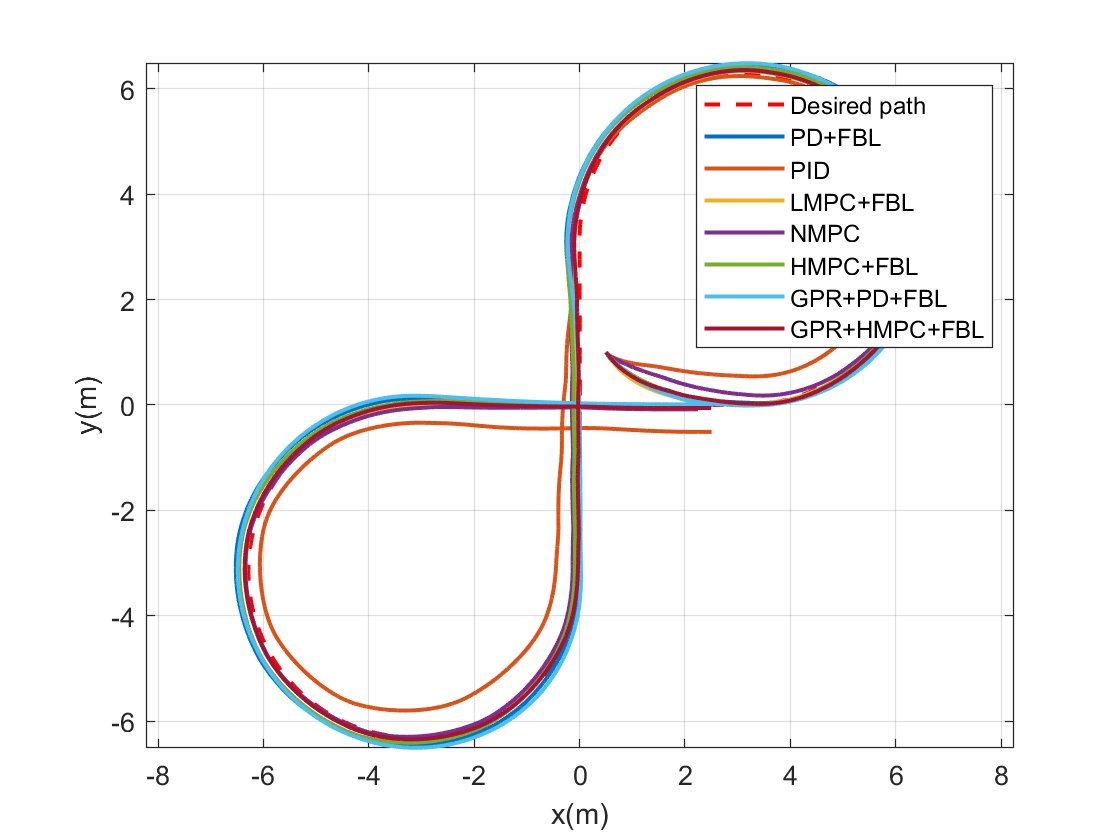

figure(1)
plot(q_d(1,:),q_d(2,:),'r--','LineWidth',1.5);
hold on
plot(q_FSF(1,:),q_FSF(2,:),'Color','#0072BD','LineWidth',1.5);
plot(q_PID(1,:),q_PID(2,:),'Color','#D95319','LineWidth',1.5);
plot(q_MPC(1,:),q_MPC(2,:),'Color','#EDB120','LineWidth',1.5);
plot(q_NMPC(1,1:N),q_NMPC(2,1:N),'Color','#7E2F8E', 'LineWidth',1.5);
plot(q_HMPC(1,1:N),q_HMPC(2,1:N),'Color','#77AC30', 'LineWidth',1.5);
plot(q_GPFSF(1,1:N),q_GPFSF(2,1:N),'Color','#4DBEEE', 'LineWidth',1.5);
plot(q_GPMPC(1,1:N),q_GPMPC(2,1:N),'Color','#A2142F', 'LineWidth',1.5);

grid on;
xlabel('x(m)')
ylabel('y(m)');
axis equal
hold off
legend('Desired path','PD+FBL','PID','LMPC+FBL','NMPC','HMPC+FBL','GPR+PD+FBL','GPR+HMPC+FBL')

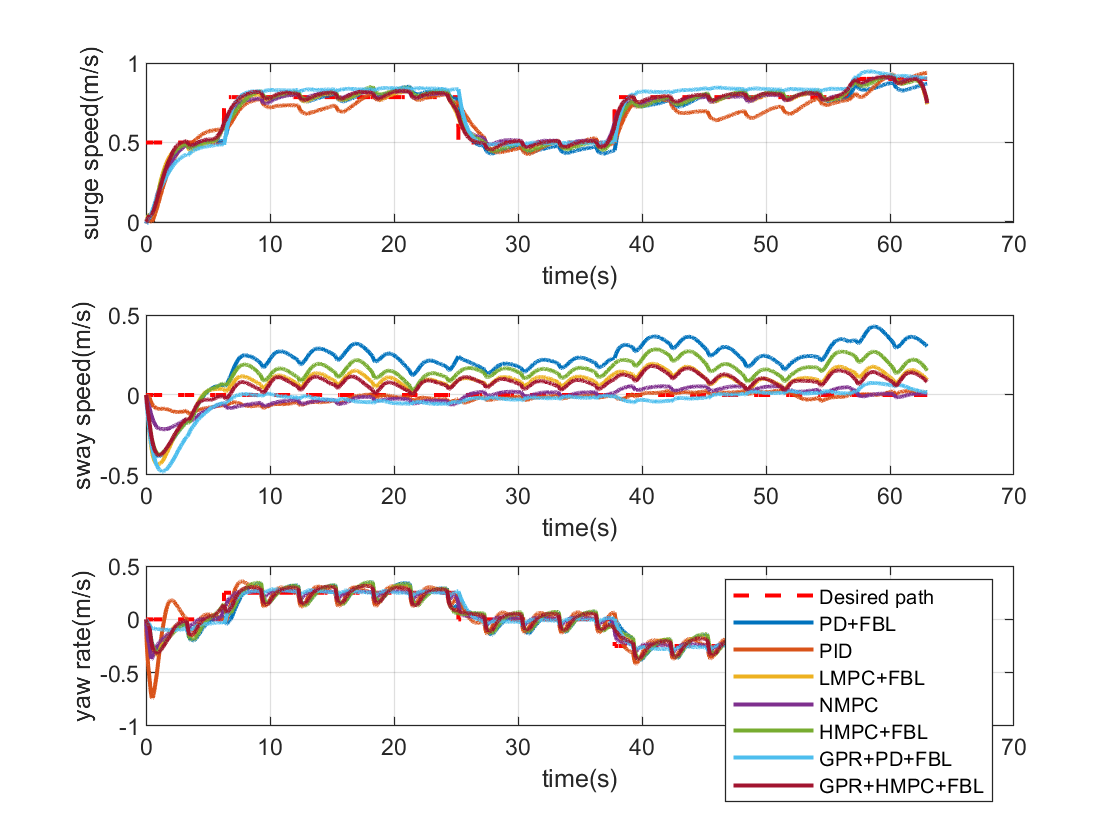





% figure(2)
% plot(T,f_PID(1,:),'r');
% hold on
% plot(T,f_PID(2,:),'b');
% hold off
% grid on;
% xlabel('time(s)')
% ylabel('Force Inputs(N)');
% ylim([-45 45])
% legend('Starboard','Port')
% 
% figure(3)
% plot(T,f_FSF(1,:),'r');
% hold on
% plot(T,f_FSF(2,:),'b');
% hold off
% grid on
% xlabel('time(s)')
% ylabel('Force Inputs(N)');
% ylim([-45 45])
% legend('Starboard','Port')
% 
% figure(4)
% plot(T,f_MPC(1,:),'r');
% hold on
% plot(T,f_MPC(2,:),'b');
% hold off
% grid on
% xlabel('time(s)')
% ylabel('Force Inputs(N)');
% ylim([-45 45])
% legend('Starboard','Port')
% 
% figure(5)
% plot(T,f_NMPC(1,:),'r');
% hold on
% plot(T,f_NMPC(2,:),'b');
% hold off
% grid on
% xlabel('time(s)')
% ylabel('Force Inputs(N)');
% ylim([-45 45])
% legend('Starboard','Port')
% 
% figure(6)
% plot(T,f_HMPC(1,1:N),'r');
% hold on
% plot(T,f_HMPC(2,1:N),'b');
% hold off
% grid on
% xlabel('time(s)')
% ylabel('Force Inputs(N)');
% ylim([-45 45])
% legend('Starboard','Port')
% 
% figure(7)
% plot(T,f_GPFSF(1,:),'r');
% hold on
% plot(T,f_GPFSF(2,:),'b');
% hold off
% grid on
% xlabel('time(s)')
% ylabel('Force Inputs(N)');
% ylim([-45 45])
% legend('Starboard','Port')
% 
% figure(8)
% plot(T,f_GPMPC(1,1:N),'r');
% hold on
% plot(T,f_GPMPC(2,1:N),'b');
% hold off
% grid on;
% xlabel('time(s)')
% ylabel('Force Inputs(N)');
% ylim([-45 45])
% legend('Starboard','Port')
% 
% 
figure(9)
subplot(3,1,1)
plot(T,q_d(4,:),'r--','LineWidth',1.5);
hold on
plot(T,q_FSF(4,:),'Color','#0072BD','LineWidth',1.5);
plot(T,q_PID(4,:),'Color','#D95319','LineWidth',1.5);
plot(T,q_MPC(4,:),'Color','#EDB120','LineWidth',1.5);
plot(T,q_NMPC(4,1:N),'Color','#7E2F8E', 'LineWidth',1.5);
plot(T,q_HMPC(4,1:N),'Color','#77AC30', 'LineWidth',1.5);
plot(T,q_GPFSF(4,1:N),'Color','#4DBEEE', 'LineWidth',1.5);
plot(T,q_GPMPC(4,1:N),'Color','#A2142F', 'LineWidth',1.5);
hold off
grid on;
xlabel('time(s)')
ylabel('surge speed(m/s)');

subplot(3,1,2)
plot(T,q_d(5,:),'r--','LineWidth',1.5);
hold on
plot(T,q_FSF(5,:),'Color','#0072BD','LineWidth',1.5);
plot(T,q_PID(5,:),'Color','#D95319','LineWidth',1.5);
plot(T,q_MPC(5,:),'Color','#EDB120','LineWidth',1.5);
plot(T,q_NMPC(5,1:N),'Color','#7E2F8E', 'LineWidth',1.5);
plot(T,q_HMPC(5,1:N),'Color','#77AC30', 'LineWidth',1.5);
plot(T,q_GPFSF(5,1:N),'Color','#4DBEEE', 'LineWidth',1.5);
plot(T,q_GPMPC(5,1:N),'Color','#A2142F', 'LineWidth',1.5);
hold off
grid on;
xlabel('time(s)')
ylabel('sway speed(m/s)');

subplot(3,1,3)
plot(T,q_d(6,:),'r--','LineWidth',1.5);
hold on
plot(T,q_FSF(6,:),'Color','#0072BD','LineWidth',1.5);
plot(T,q_PID(6,:),'Color','#D95319','LineWidth',1.5);
plot(T,q_MPC(6,:),'Color','#EDB120','LineWidth',1.5);
plot(T,q_NMPC(6,1:N),'Color','#7E2F8E', 'LineWidth',1.5);
plot(T,q_HMPC(6,1:N),'Color','#77AC30', 'LineWidth',1.5);
plot(T,q_GPFSF(6,1:N),'Color','#4DBEEE', 'LineWidth',1.5);
plot(T,q_GPMPC(6,1:N),'Color','#A2142F', 'LineWidth',1.5);
hold off
grid on;
xlabel('time(s)')
ylabel('yaw rate(m/s)');
legend('Desired path','PD+FBL','PID','LMPC+FBL','NMPC','HMPC+FBL','GPR+PD+FBL','GPR+HMPC+FBL')